addpath('utils');

## Read data

load('datasets/MNIST_M/MNIST_test_small.mat');
X1 = data;
y1 = labels;

## SPCA through DAPCA

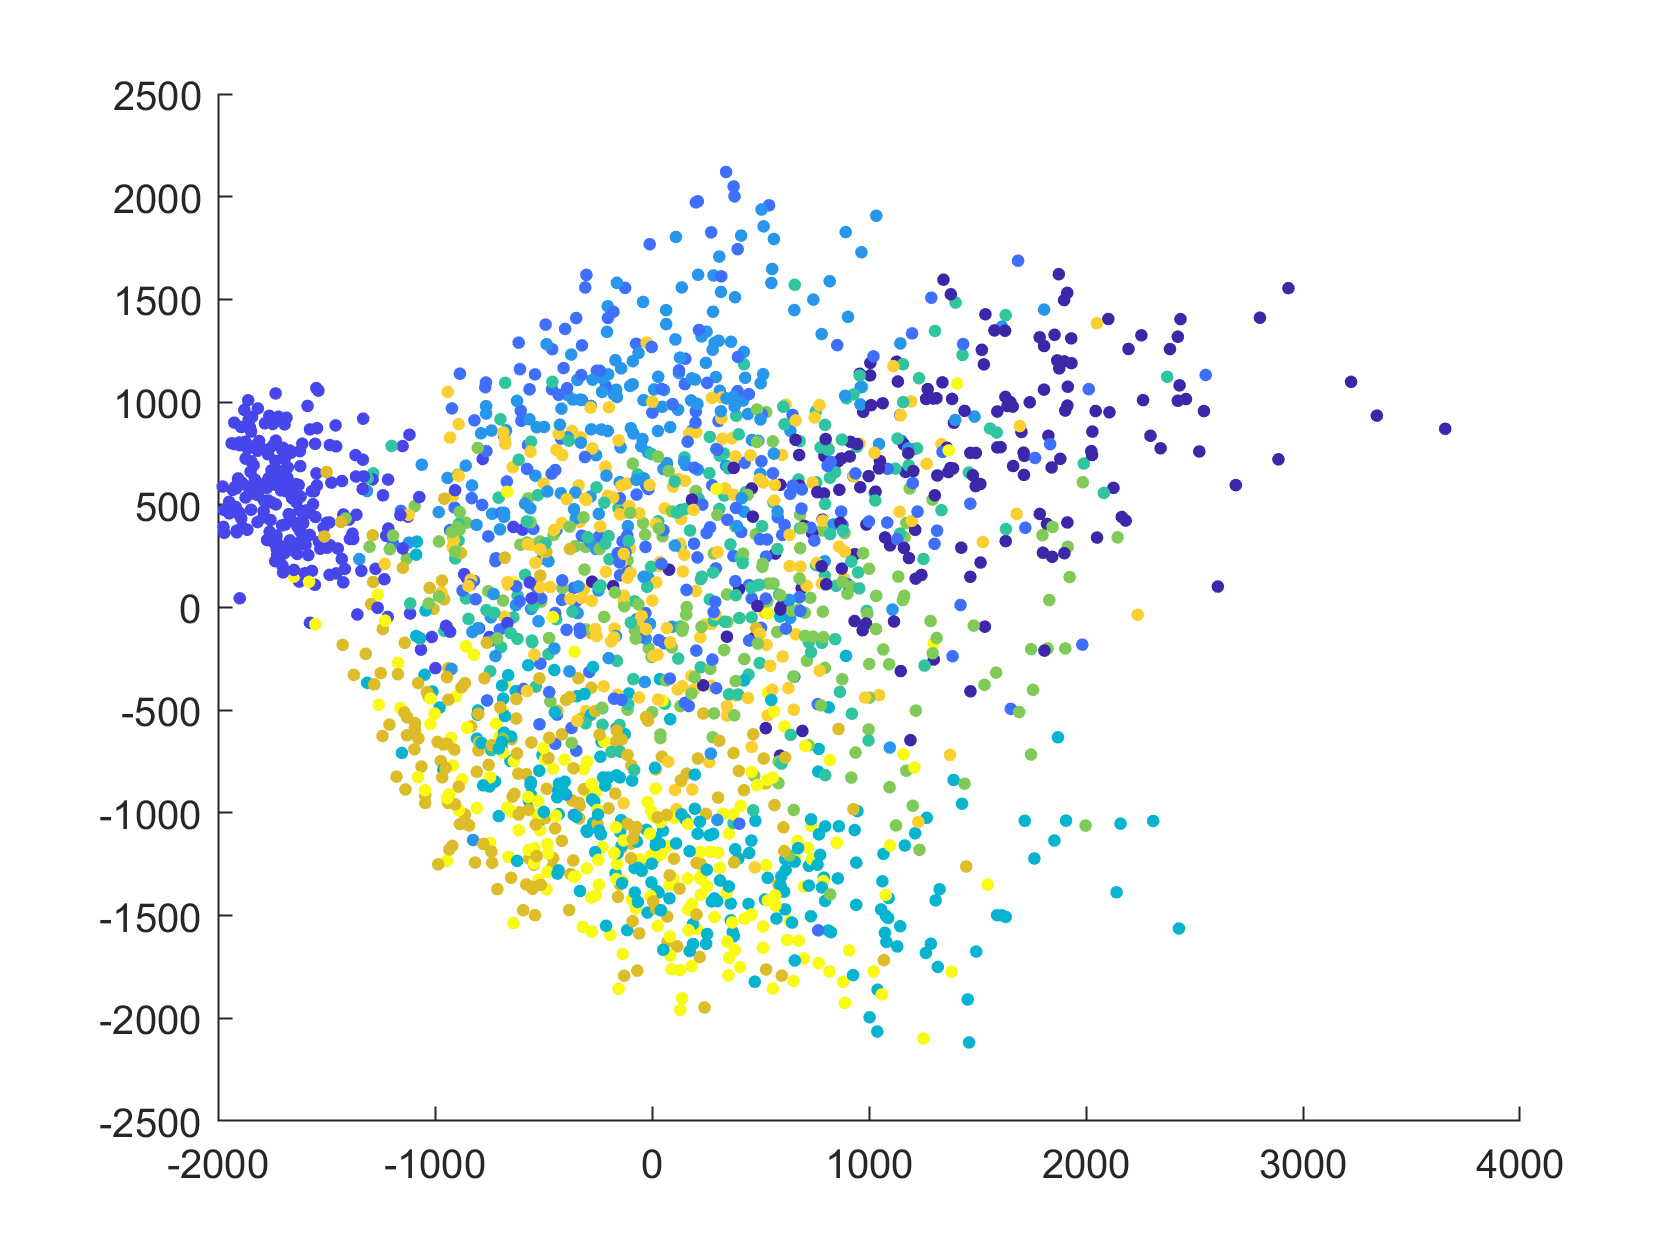

[v,u] = pca(X1);
scatter(u(:,1),u(:,2),10,y1,'filled');

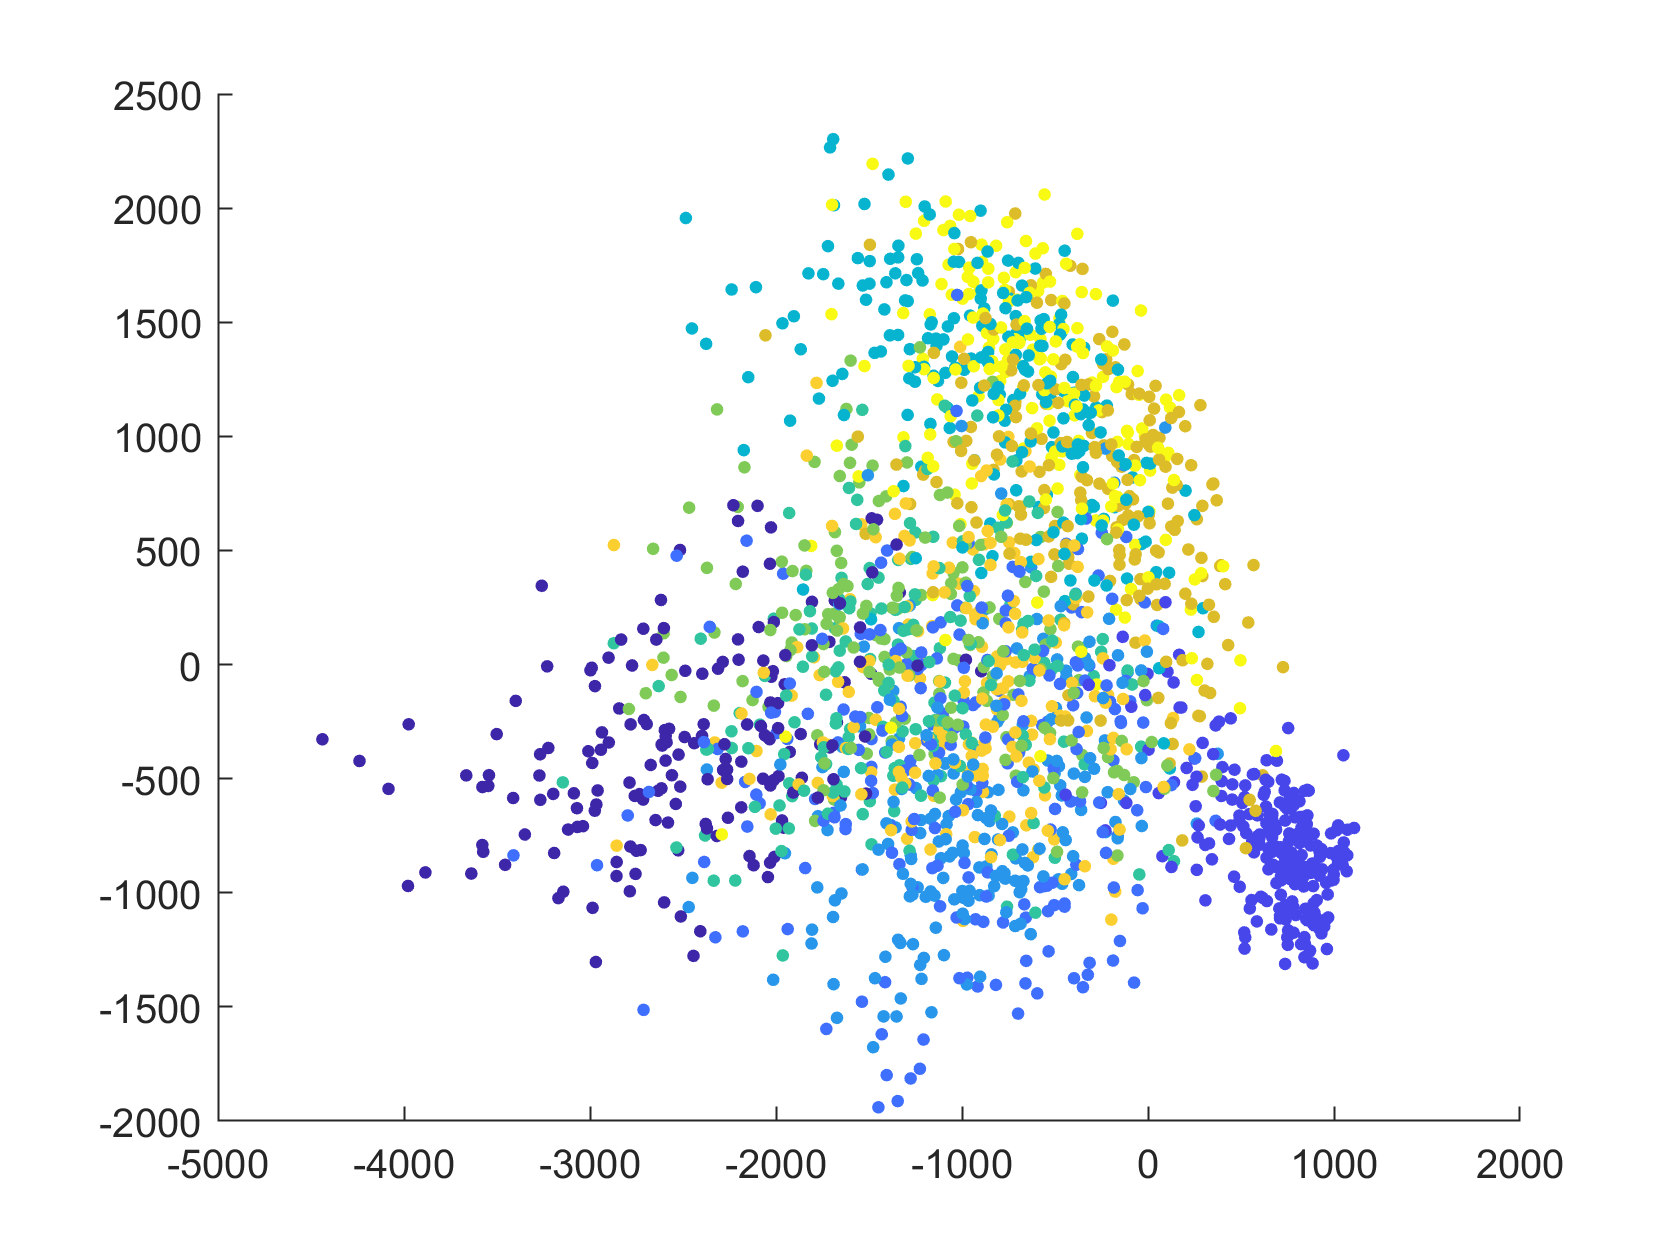

alpha = 1; 
figure; [ V, D ] = SupervisedPCA(X1, y1, 2, alpha); u = X1*V; scatter(u(:,1),u(:,2),10,y1,'filled');

[V1, D1, PX, PY] = DAPCA(X1, y1, [], 2, 'alpha', alpha);

PX

PX = 2000×2 single matrix
	1.0e+03 *

    3.3743    0.1416
    3.3046    1.2540
    3.3024    0.1358
    4.4582    0.2686
    3.4638    0.9051
    2.6661    0.4859
    2.3417    0.2041
    4.4042    1.1183
    2.8944    0.5546
    2.4011    0.7036


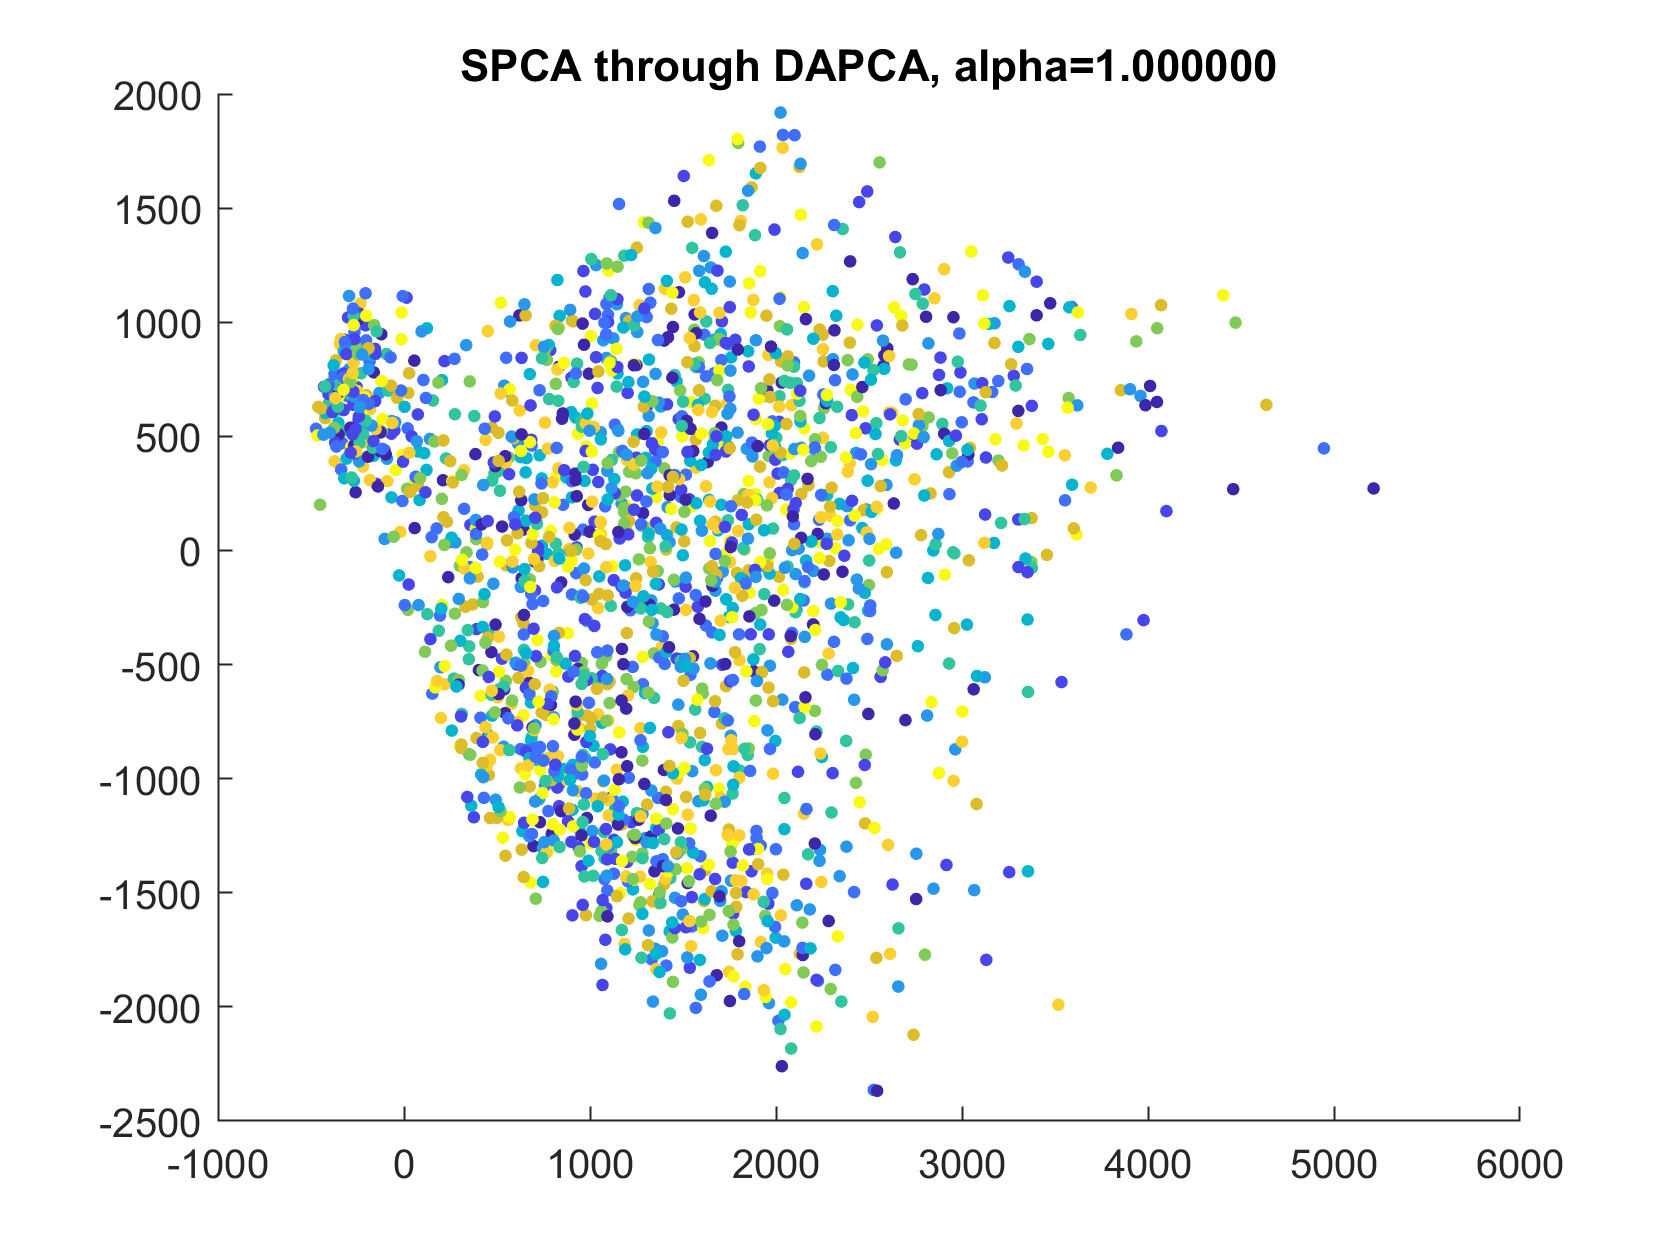

% Drawing
figure; 
scatter(PX(:,1), PX(:,2), 10, y1, 'filled'); 
title(sprintf('SPCA through DAPCA, alpha=%f', alpha));
saveFigures(sprintf('Figures\\DAPCA_alpha_%4.2f.png', alpha));

data = data(1:2000,:);
labels = labels(1:2000)

labels = 1×2000 int64 row vector
   7   2   1   0   4   1   4   9   5   9   0   6   9   0   1   5   9   7   3   4   9   6   6   5   4   0   7   4   0   1   3   1   3   4   7   2   7   1   2   1   1   7   4   2   3   5   1   2   4   4


save('datasets/MNIST_M/MNIST_test_small.mat','data','labels')

alpha = 1;
delta = [1,2,3,4,1,2,3,4,1,2];
[V2, D2, PXd, PYd] = DAPCA(X1, y1, [], 2, 'alpha', alpha, 'delta', delta);

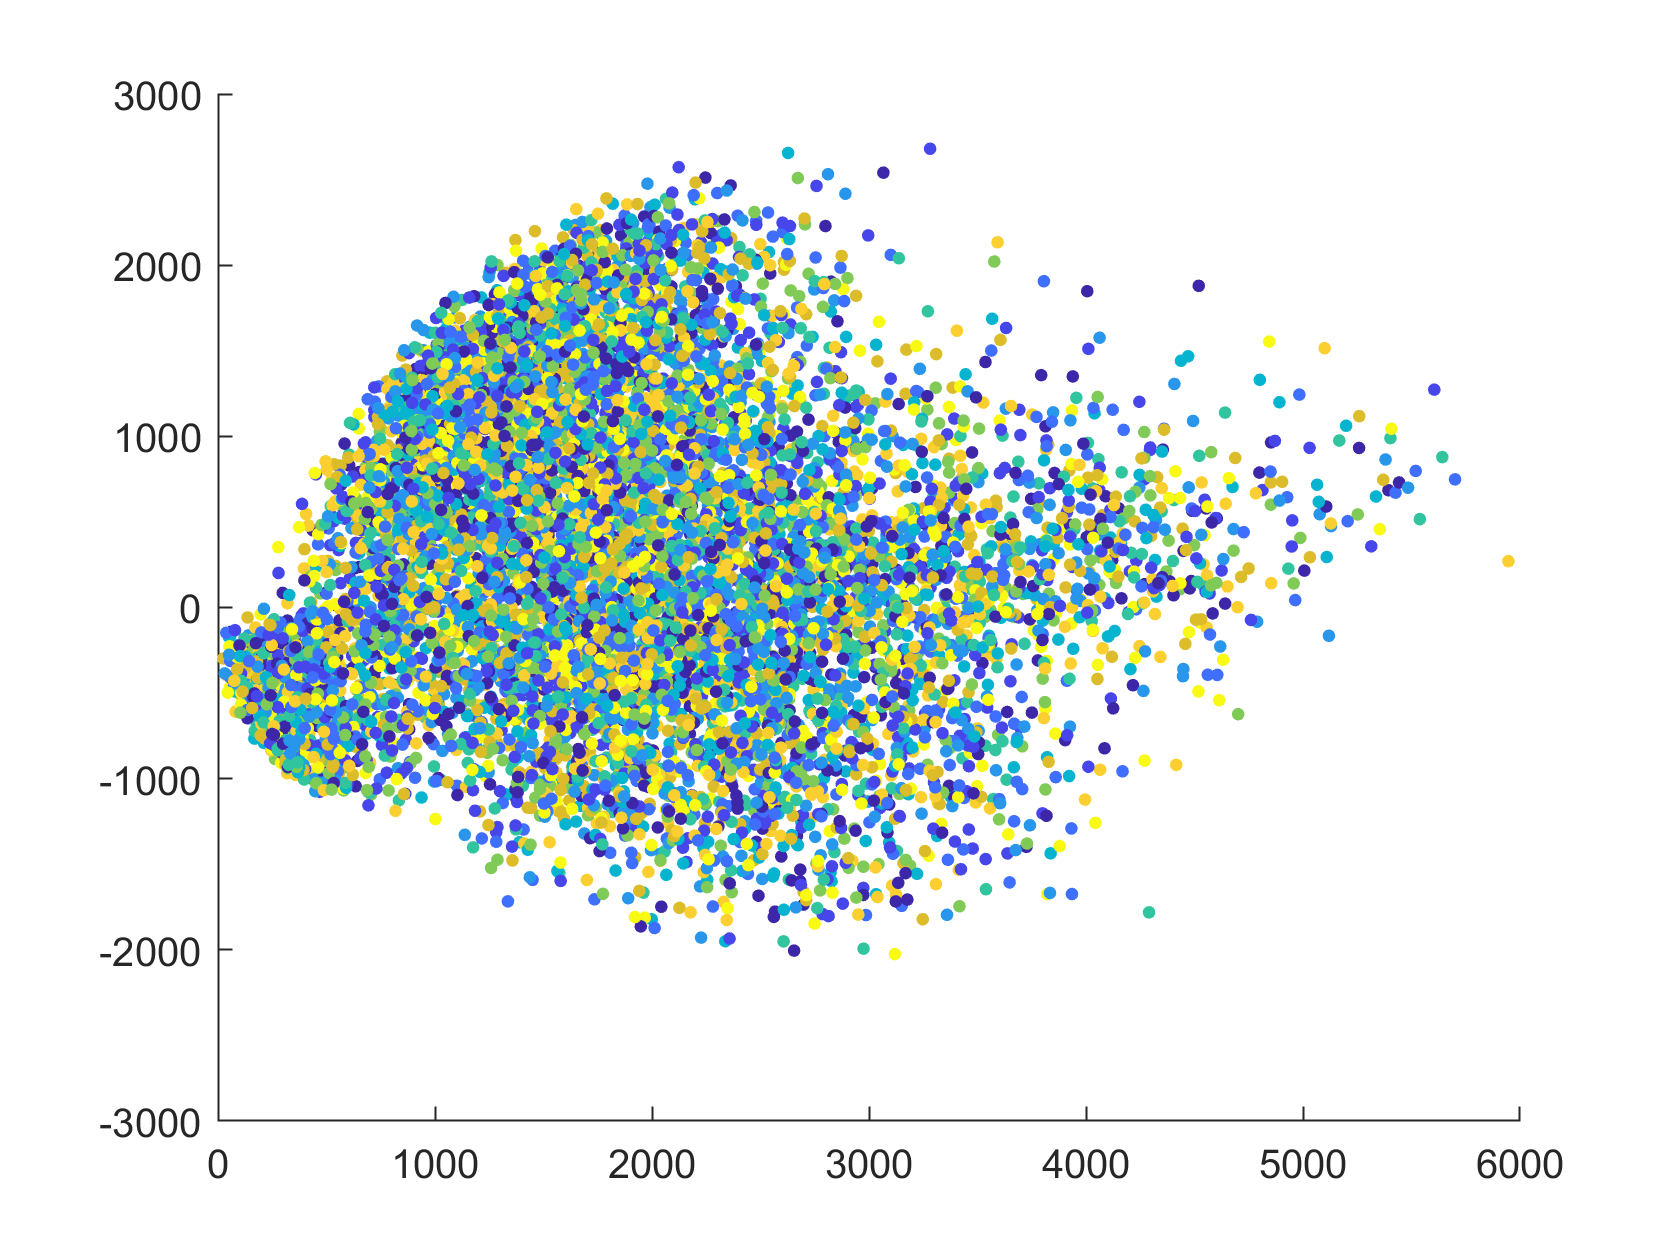

% Drawing
figure; 
scatter(PXd(:,1),PXd(:,2),10,labels,'filled'); 

% title(sprintf('SPCA through DAPCA, alpha=%4.2f, delta = [%4.2f,%4.2f,%4.2f]', alpha, delta));
% saveFigures(sprintf('Figures\\DAPCA_alpha_%4.2f_delta_[%4.2f,%4.2f,%4.2f].png', alpha, delta));

## Figure with Y for comparison

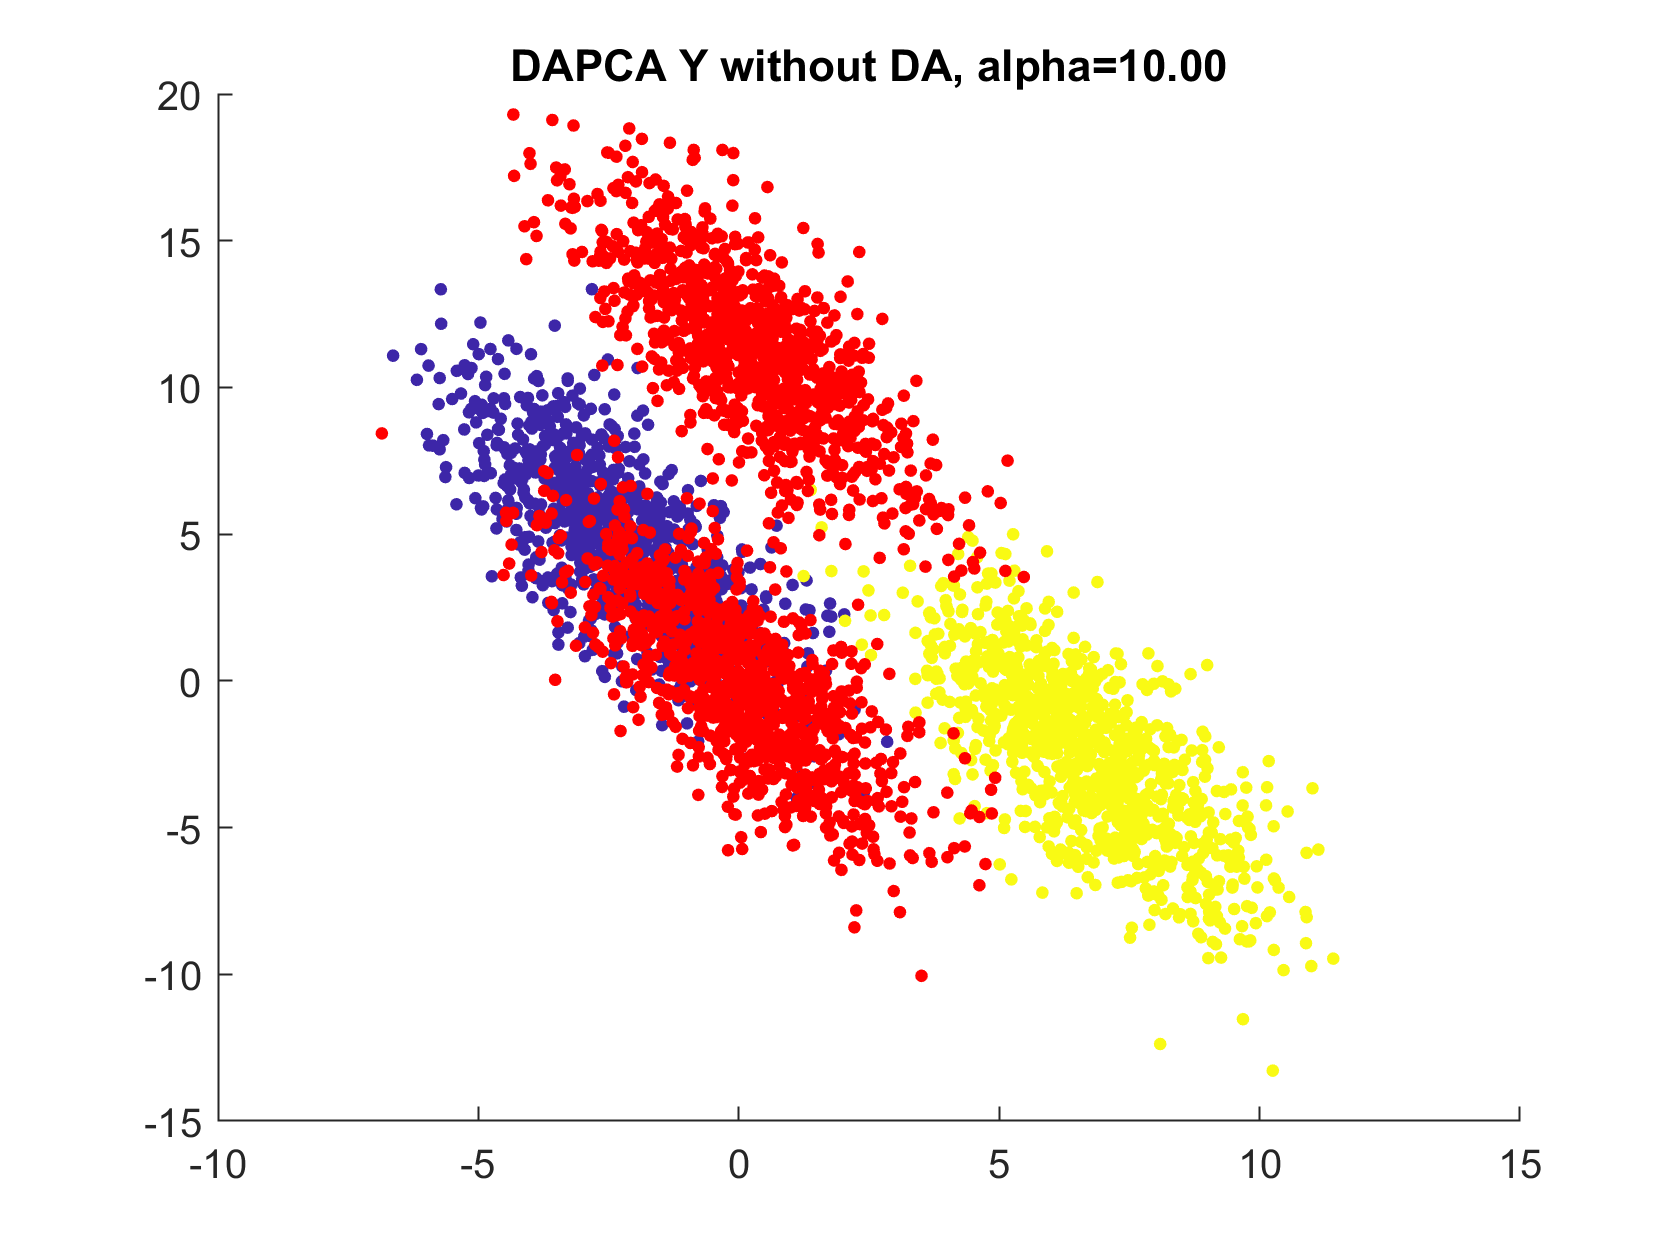

PY = Y * V1;
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA Y without DA, alpha=%4.2f', alpha));
saveFigures(sprintf('Figures\\DAPCA Y without Y in search, alpha %4.2f.png', alpha));

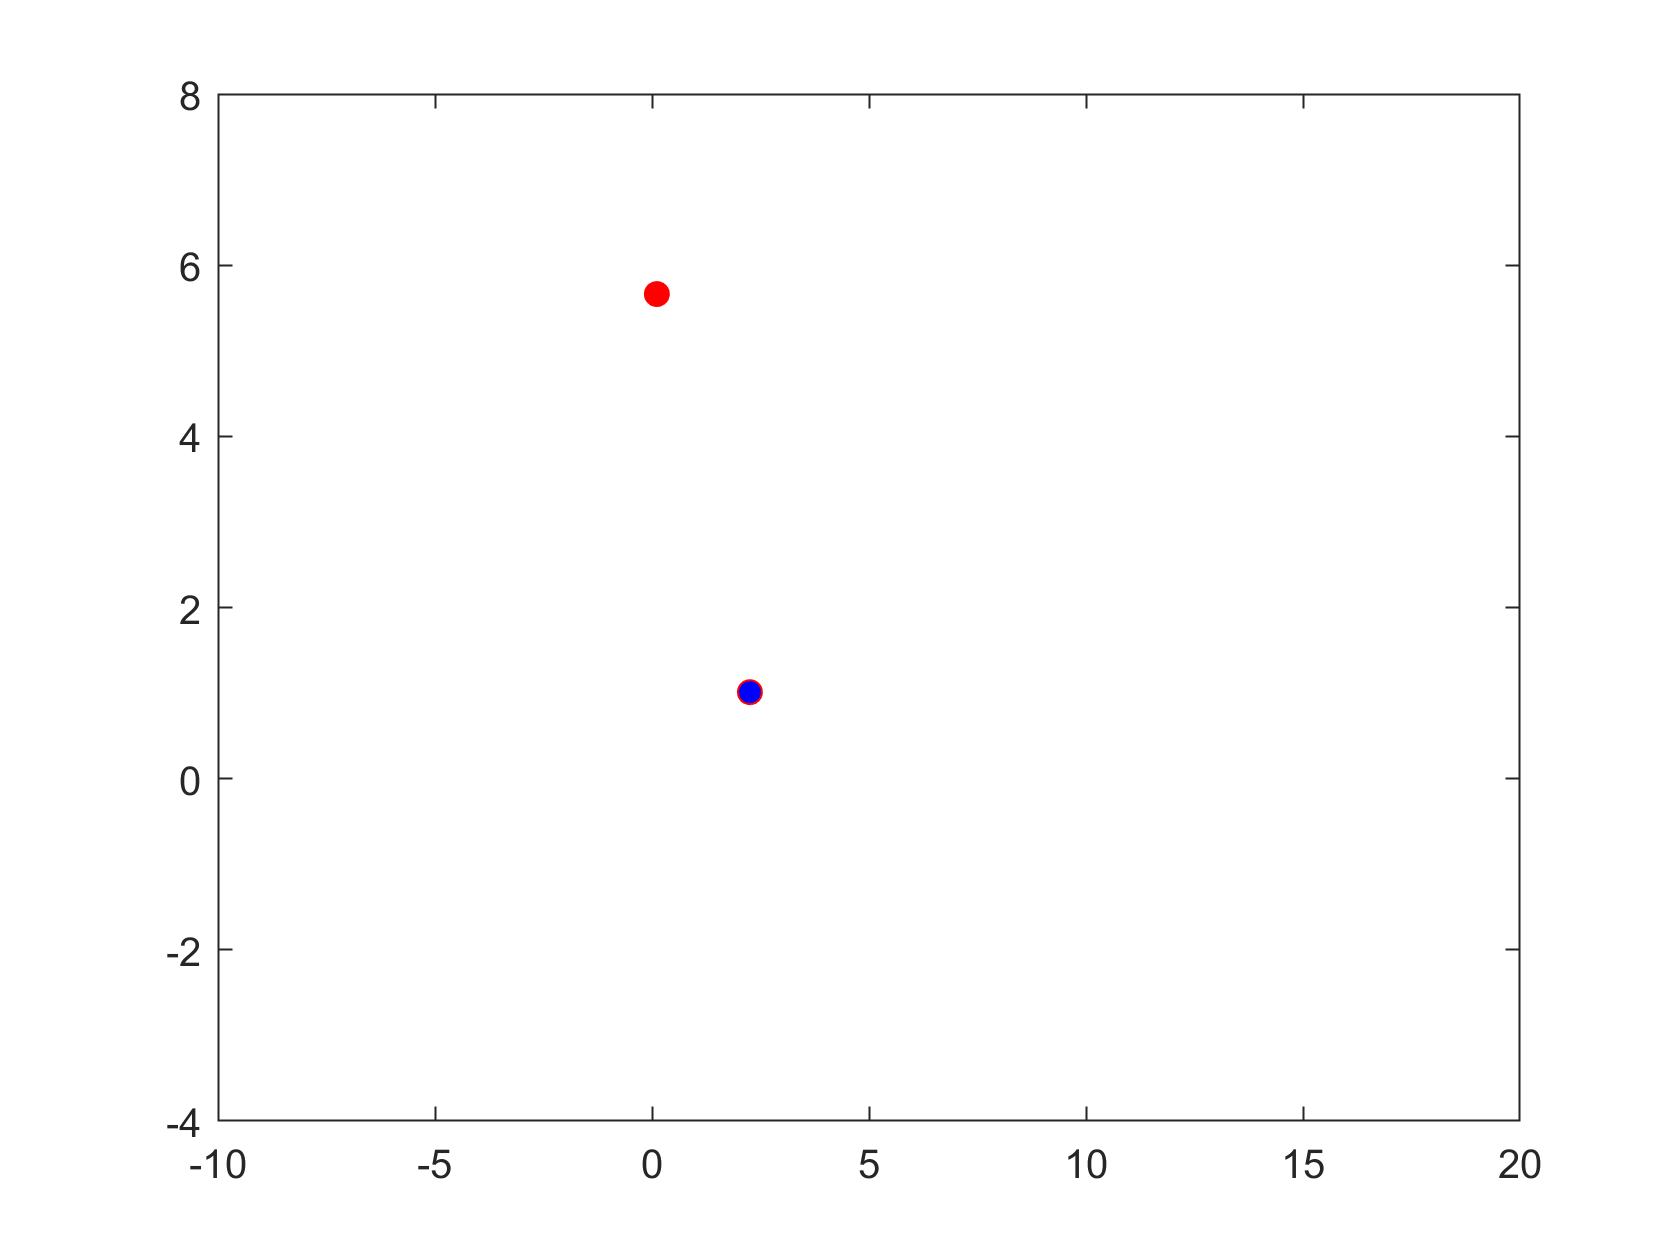

% Draw centroids
figure
mi = mean(PX);
plot(mi(1),mi(2),'or','markerfacecolor', 'b');
hold on;
mi = mean(PY);
plot(mi(1),mi(2),'or','markerfacecolor', 'r');
xlim([-10, 20]);
ylim([-4, 8]);
saveFigures(sprintf('Figures\\Centroids DAPCA Y without Y in search, alpha %4.2f.png', alpha));

## Redraw for shifted Y

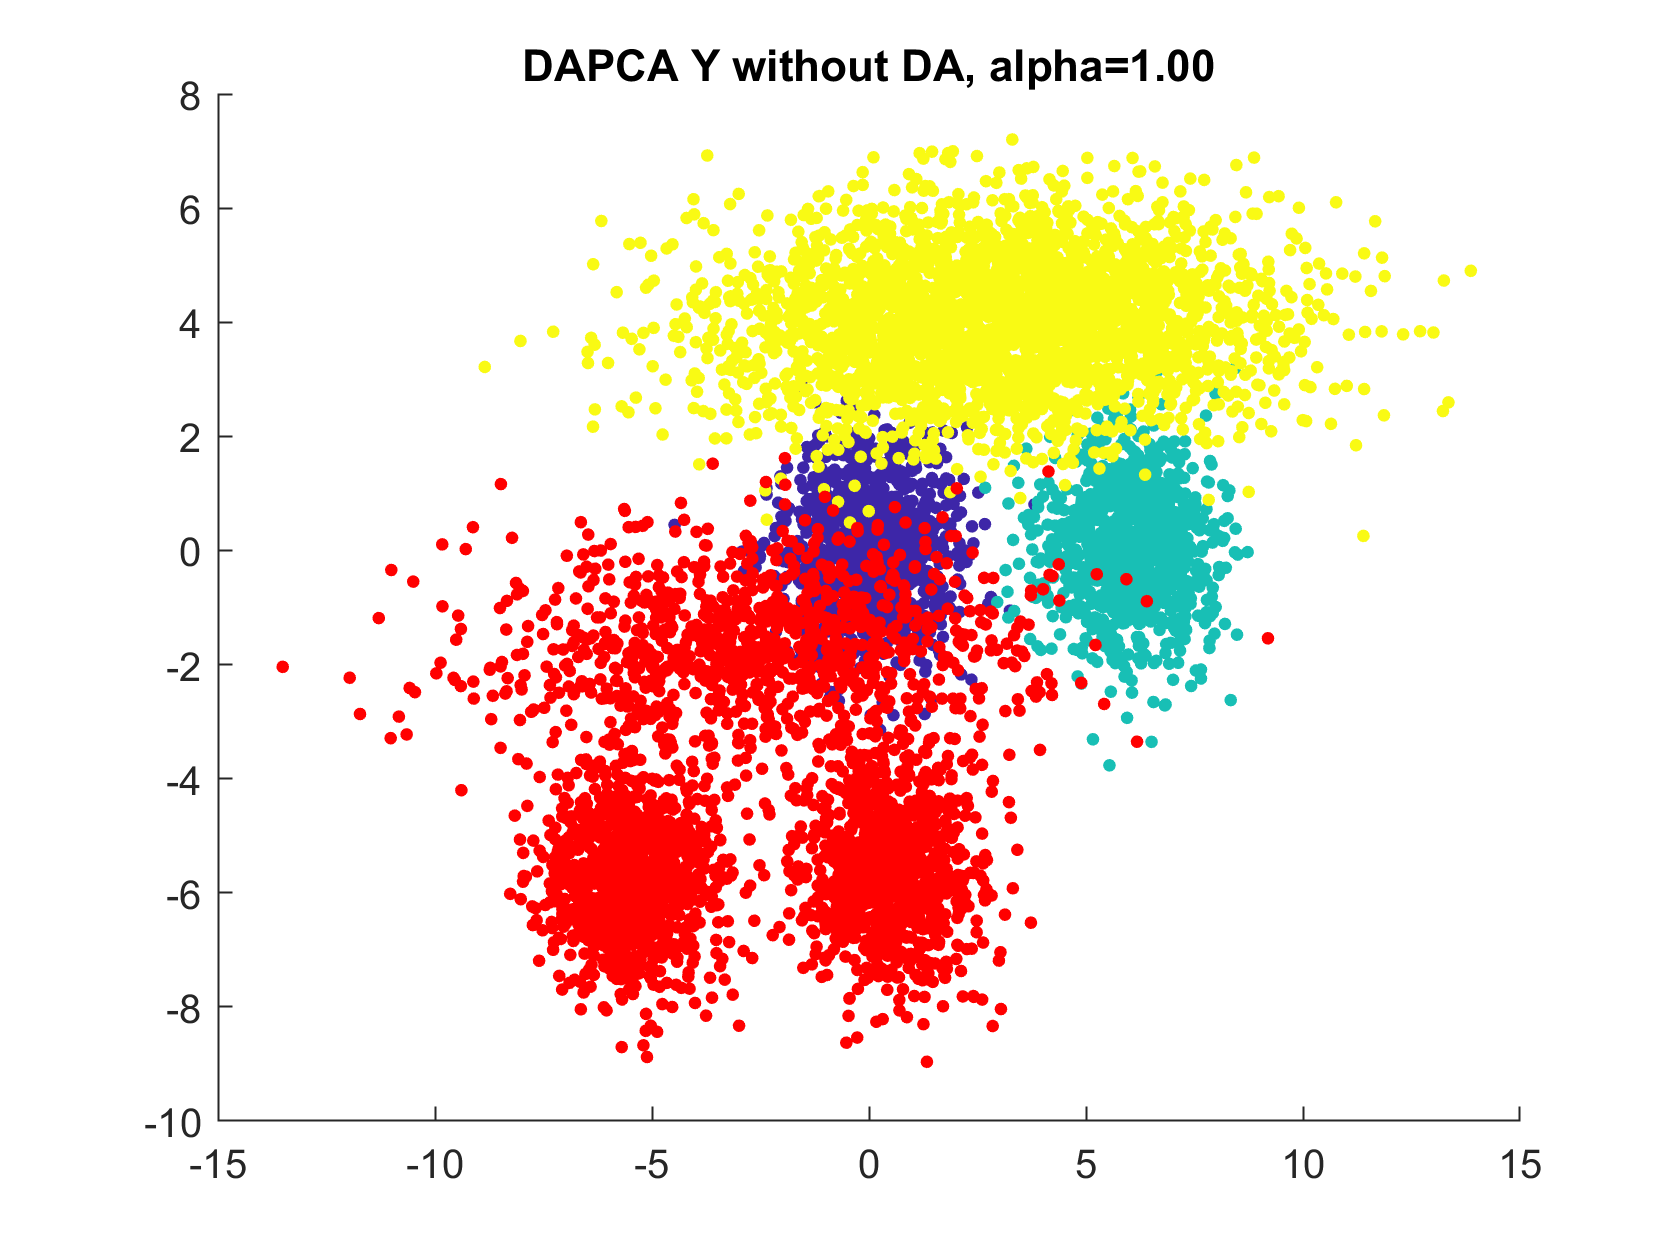

PY = (Y - 5) * V1;
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA Y without DA, alpha=%4.2f', alpha));
saveFigures(sprintf('Figures\\DAPCA SY without Y in search, alpha %4.2f.png', alpha));

## Repulsion in Y

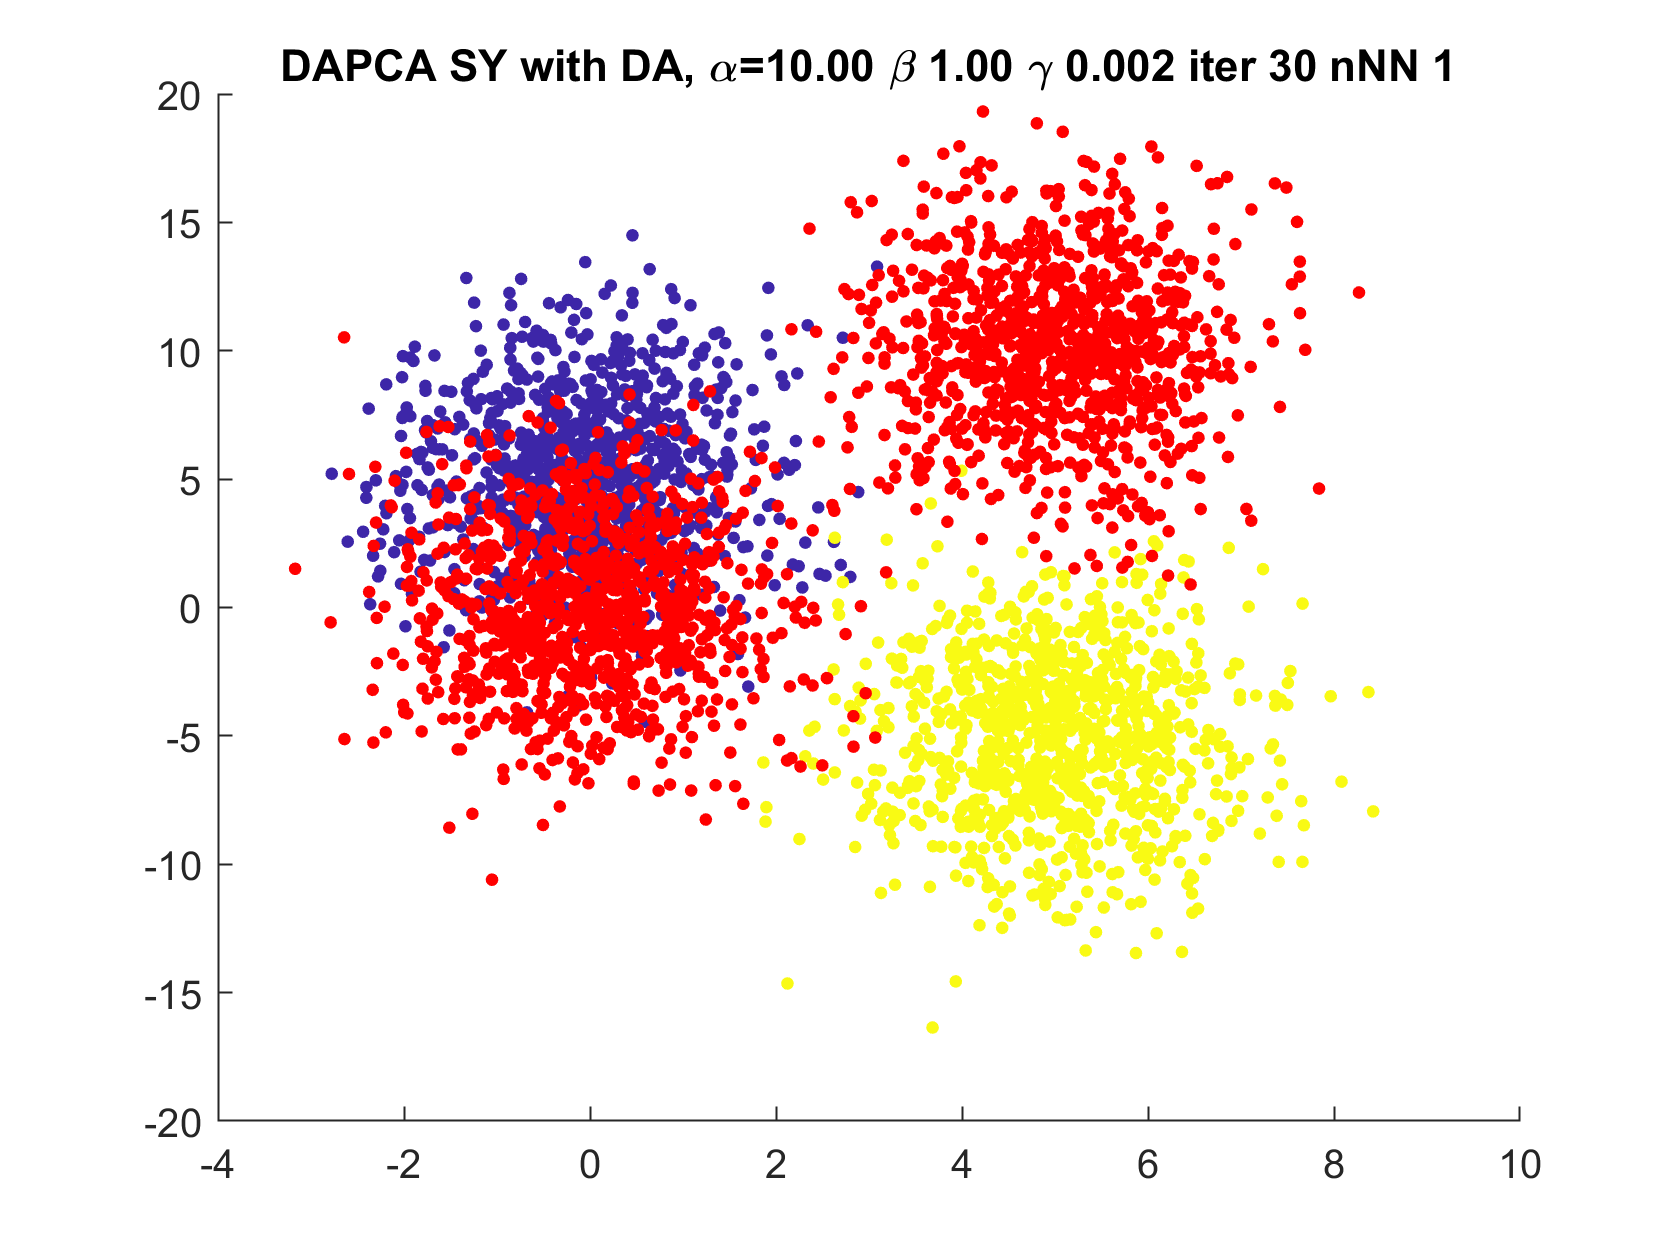

beta = 1;
delta = 1;
alpha = 10;
gamma = 0.0015;
maxIter = 30;
SY = Y;
kNN = 1;
[V, D, PX, PY] = DAPCA(X, labels, SY, 2, 'alpha', alpha, 'beta', beta, 'gamma', gamma, 'maxiter', maxIter, 'kNN', kNN);
% Draw
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA SY with DA, \\alpha=%4.2f \\beta %4.2f \\gamma %5.3f iter %d nNN %d', alpha, beta, gamma, maxIter, kNN));
saveFigures(sprintf('Figures\\DAPCA Y with DA, alpha %4.2f beta %4.2f gamma %5.3f iter %d nNN %d.png', alpha, beta, gamma, maxIter, kNN));

## Recalculation for three steps

PC1 = [];
PC2 = [];
meanDist = [];
for maxIter = 1:3
    [V, D, PX, PY] = DAPCA(X, labels, SY, 2, 'alpha', alpha, 'beta', beta, 'gamma', gamma, 'maxiter', maxIter, 'kNN', kNN);
    PC1 = [PC1, V(:, 1)];
    PC2 = [PC2, V(:, 2)];
    meanDist = [meanDist, sum((mean(PX) - mean(PY)) .^ 2)];
    disp(meanDist)
end

    6.5695

    6.5695    6.5796

    6.5695    6.5796    6.5798



Angles calculation

tmp = PC1' * PC1;
tmp(tmp > 1) = 1;
PC1a = acosd(tmp);
tmp = PC2' * PC2;
tmp(tmp > 1) = 1;
PC2a = acosd(tmp);

## Comparison of V with the first elements of PC1 and PC2

ang1 = acosd(V(:, 1)' * PC1(:, 1));
ang2 = acosd(V(:, 2)' * PC2(:, 1));
mDist = sum((mean(PX) - mean(PY)) .^ 2);